clc;
clear all;
close all;
Fs = 4000;
channels = 1;
bits = 16;
r = audiorecorder(Fs, bits, channels); % Audio recording function
duration = 2;
disp('Recording Started');

Recording Started


recordblocking(r, duration); 
disp('Recording stopped'); 

Recording stopped


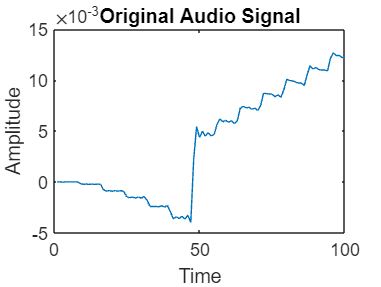

y = getaudiodata(r); % Store audio data in variable X
audiowrite('sample.wav', y, Fs); % Save audio as 'sample.wav'

N = 1:100; % Length of audio we are interested in
Signal = y(N); % Extract the specified length of the signal
ho = fft(y);
homomorphic_signal = log(abs(ho));
cepstrum=ifft(homomorphic_signal);
[pks, locs] = findpeaks(cepstrum, 'MinPeakDistance', round(Fs / 1000)); % Adjust MinPeakDistance as needed

% Convert peak locations to pitch frequencies
pitch_frequencies = Fs./(locs - 1);
pitch_hz = max(pitch_frequencies);

% Step 4: Display the results
figure;
% subplot(2, 2, 1);
plot(Signal);
title('Original Audio Signal');
xlabel('Time');
ylabel('Amplitude');

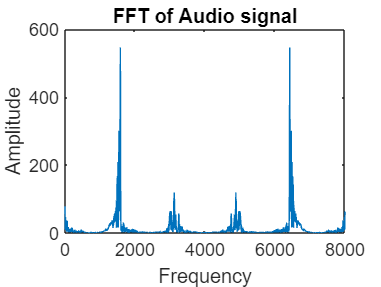


figure;
% subplot(2, 2, 2);
plot(abs(ho));
title('FFT of Audio signal');
xlabel('Frequency');
ylabel('Amplitude');

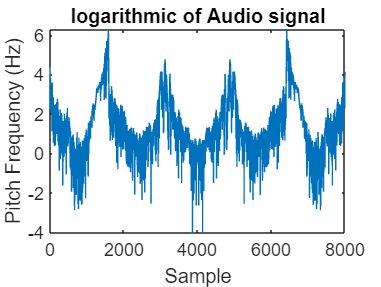


figure;
% subplot(2, 2, 3);
plot(homomorphic_signal);
xlabel('Sample');
ylabel('Pitch Frequency (Hz)');
title('logarithmic of Audio signal');

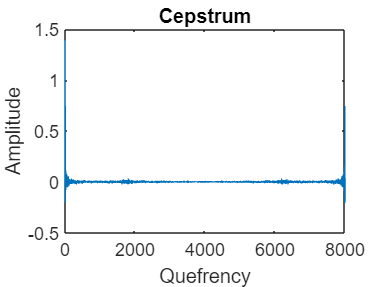


figure;
% subplot(2, 2, 4);
plot(cepstrum);
xlabel('Quefrency');
ylabel('Amplitude');
title('Cepstrum');


fprintf('Pitch: %.2f Hz\n', pitch_hz)

Pitch: 800.00 Hz
